addpath myFunction\myftn\
clearvars -except Gfinal0T ImgFinalZnorm vm x y Zfinal0T
;close;clc

fn = "RawData\1T-TaS2(point defect)\Gxy0T.mat"

fn = "RawData\1T-TaS2(point defect)\Gxy0T.mat"

loadif(fn)

fldNm = 6×1 cell array
    {'Zfinal0T'     }
    {'x'            }
    {'vm'           }
    {'ImgFinalZnorm'}
    {'y'            }
    {'Gfinal0T'     }



Your variables are:

fldNm  fn     mt     



ans = 'already'

Visible on

gr  = groot();
gr.Units = "normalized";
mp = gr.MonitorPositions;
f1 = figure(1);
f1.Units  = "normalized";
f1.Position = secondNormalization(mp(1,:),[0 0 1 1]);
f1.Visible = "on";

subplotting

msb = 3

msb = 3

nsb = 5

nsb = 5

axReal = subplot(msb,nsb,1:10)

axReal =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.4096 0.7750 0.5154]
            Units: 'normalized'

  Show all properties


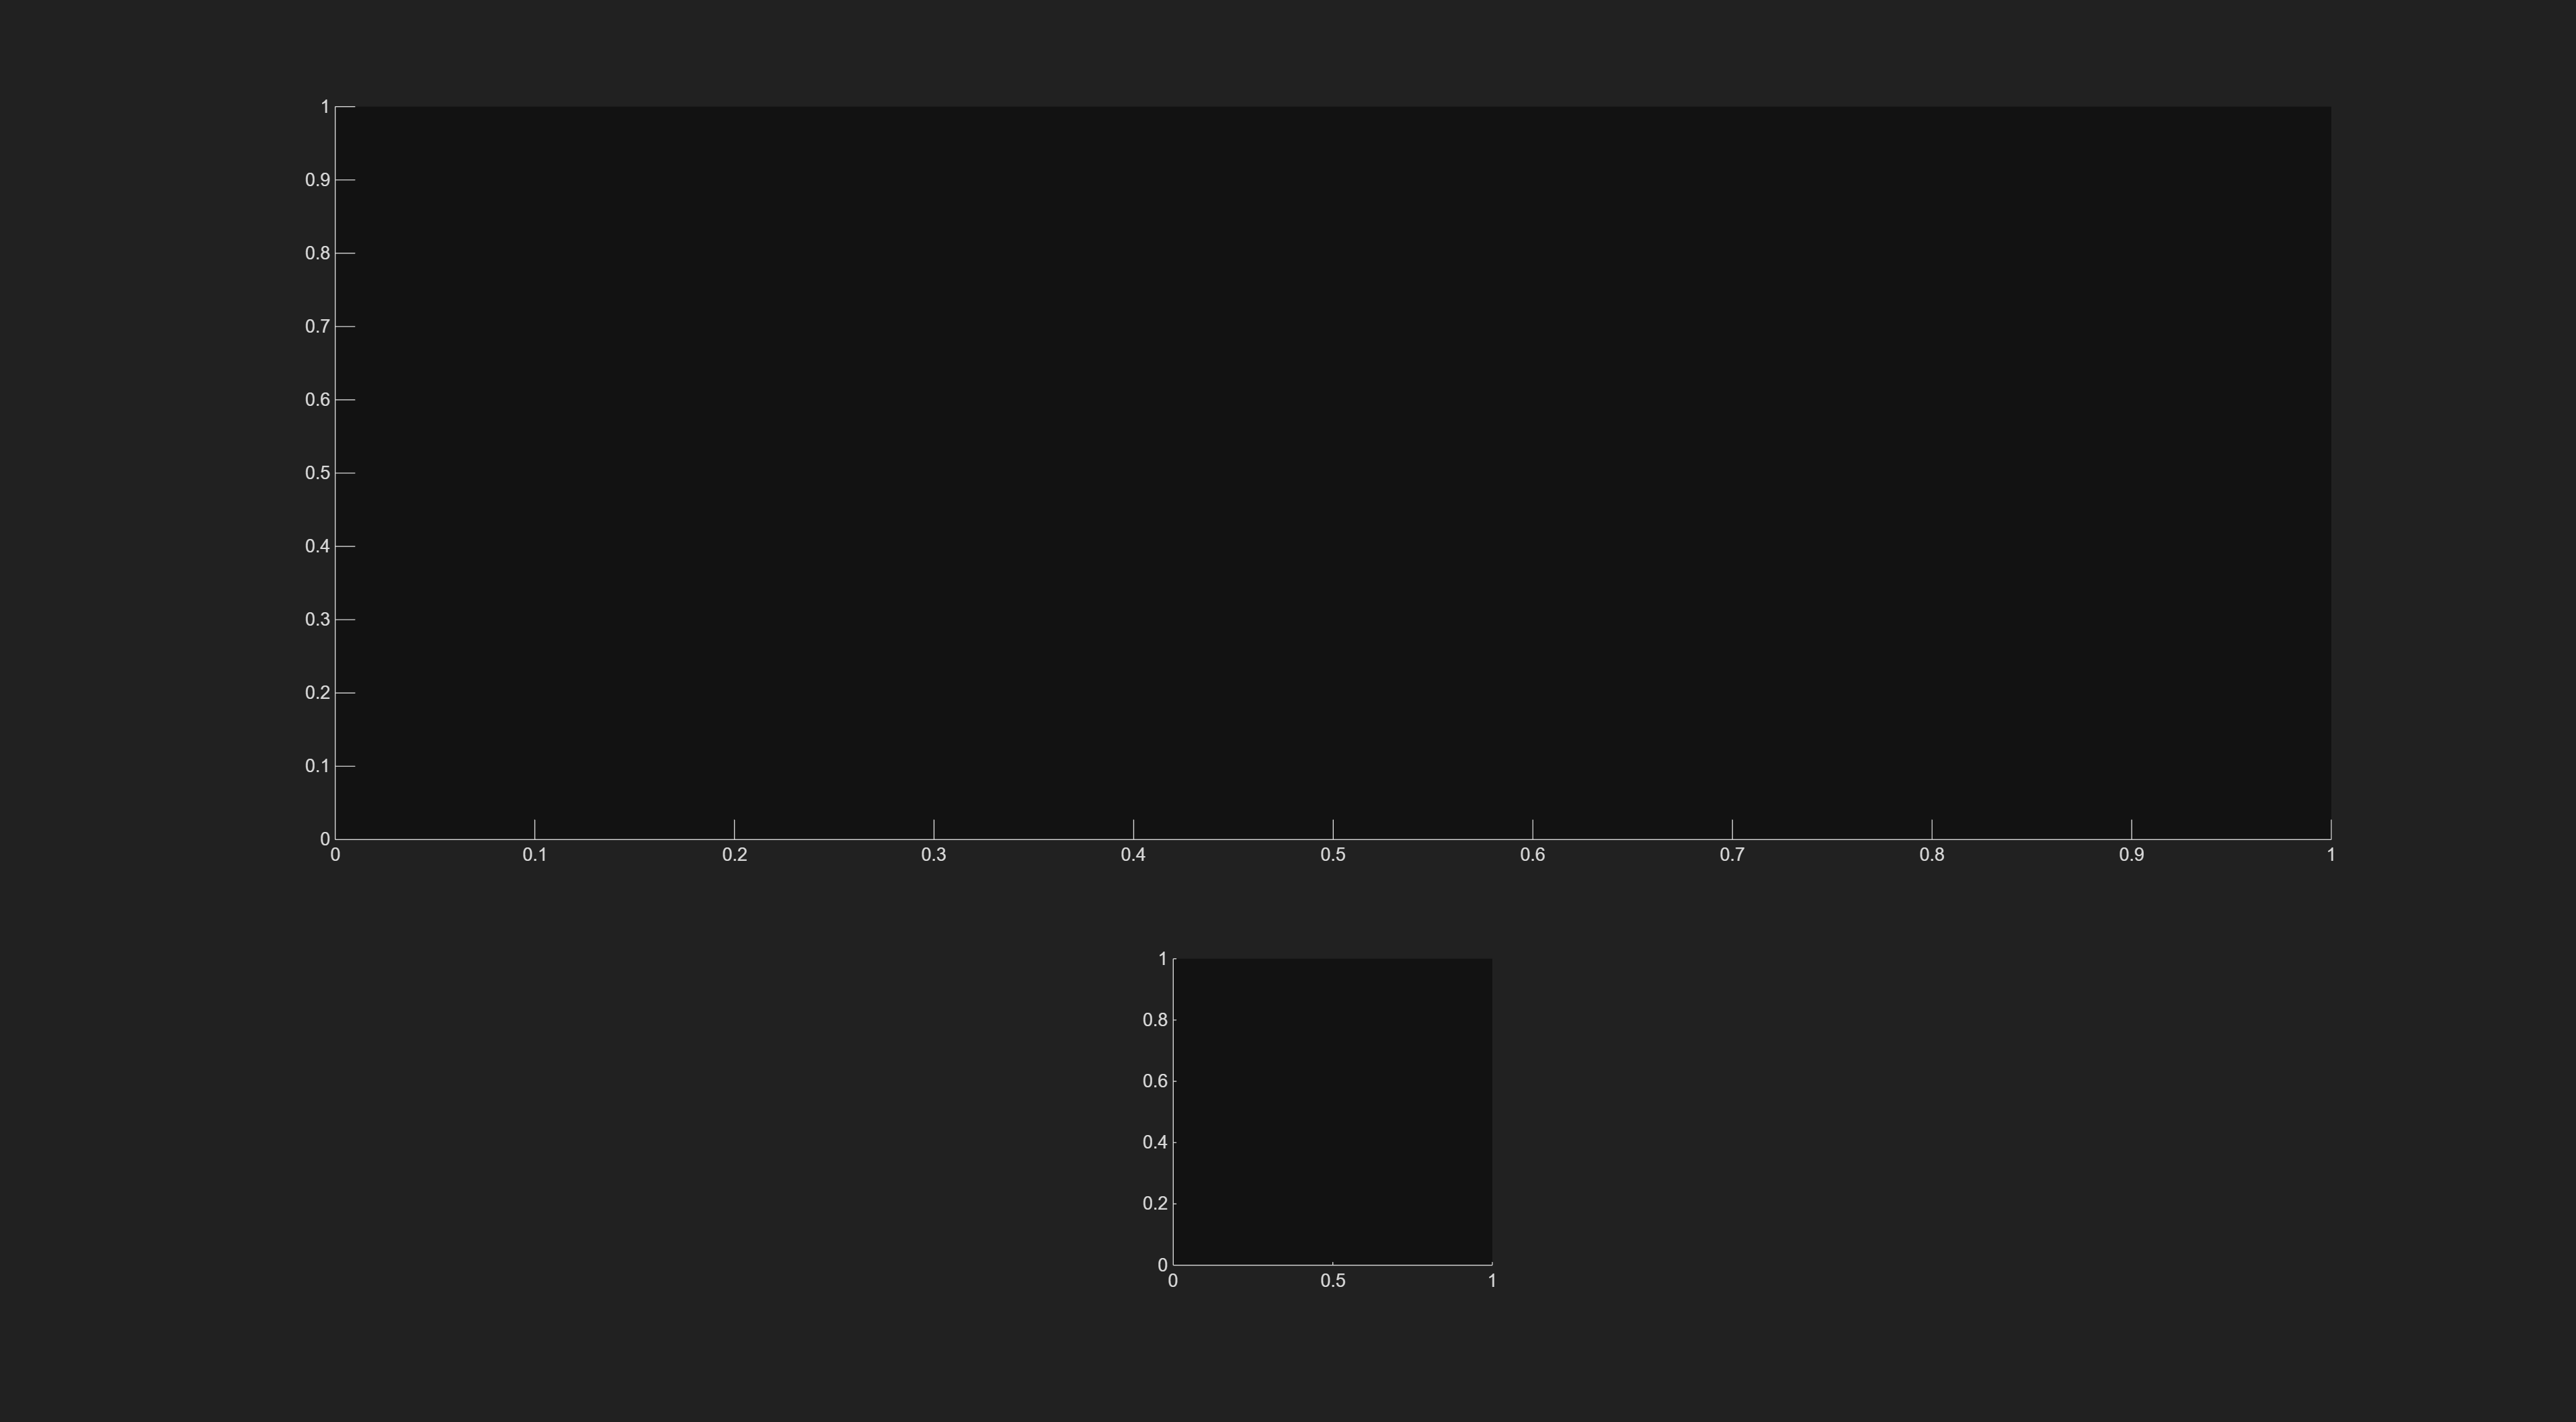

axDos =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.4556 0.1100 0.1237 0.2157]
            Units: 'normalized'

  Show all properties


axDos = subplot(msb,nsb,13)

imgInfo = 1

imgInfo = 1

iv = 194

iv = 194

xpxl = 380

xpxl = 380

ypxl = 318

ypxl = 318

vNow = vm(iv)

vNow = -0.5670

Topography

f1.CurrentAxes = axReal

f1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.1294 0.1294 0.1294]
    Position: [0.0027 1.2528 0.7484 0.7347]
       Units: 'normalized'

  Show all properties


if imgInfo == 1
    imgfoo = ImgFinalZnorm;
elseif imgInfo == 2
    imgfoo = Gfinal0T(:,:,iv)
end

imagesc(imgfoo')
axis image
ax = gca

ax =   Axes with properties:

             XLim: [0.5000 1.7415e+03]
             YLim: [0.5000 729.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.4096 0.7750 0.5154]
            Units: 'normalized'

  Show all properties


ax.YDir = 'normal'

ax =   Axes with properties:

             XLim: [0.5000 1.7415e+03]
             YLim: [0.5000 729.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.4096 0.7750 0.5154]
            Units: 'normalized'

  Show all properties



xlabel('x')
ylabel('y')
if imgInfo == 1
    colormap gray



elseif imgInfo == 2
    colormap jet
end

% hold on
% plot(xpxl,ypxl,'ro')
% 
% hold off

Determine Segment Region

margins = [700 770]

margins =    700   770


co = colororder()

co =     0.1490    0.5490    0.8660
    0.9600    0.4660    0.1600
    1.0000    0.9090    0.3920
    0.7520    0.3600    0.9840
    0.2860    0.8580    0.2500
    0.4230    0.9560    1.0000
    0.9490    0.4030    0.7720


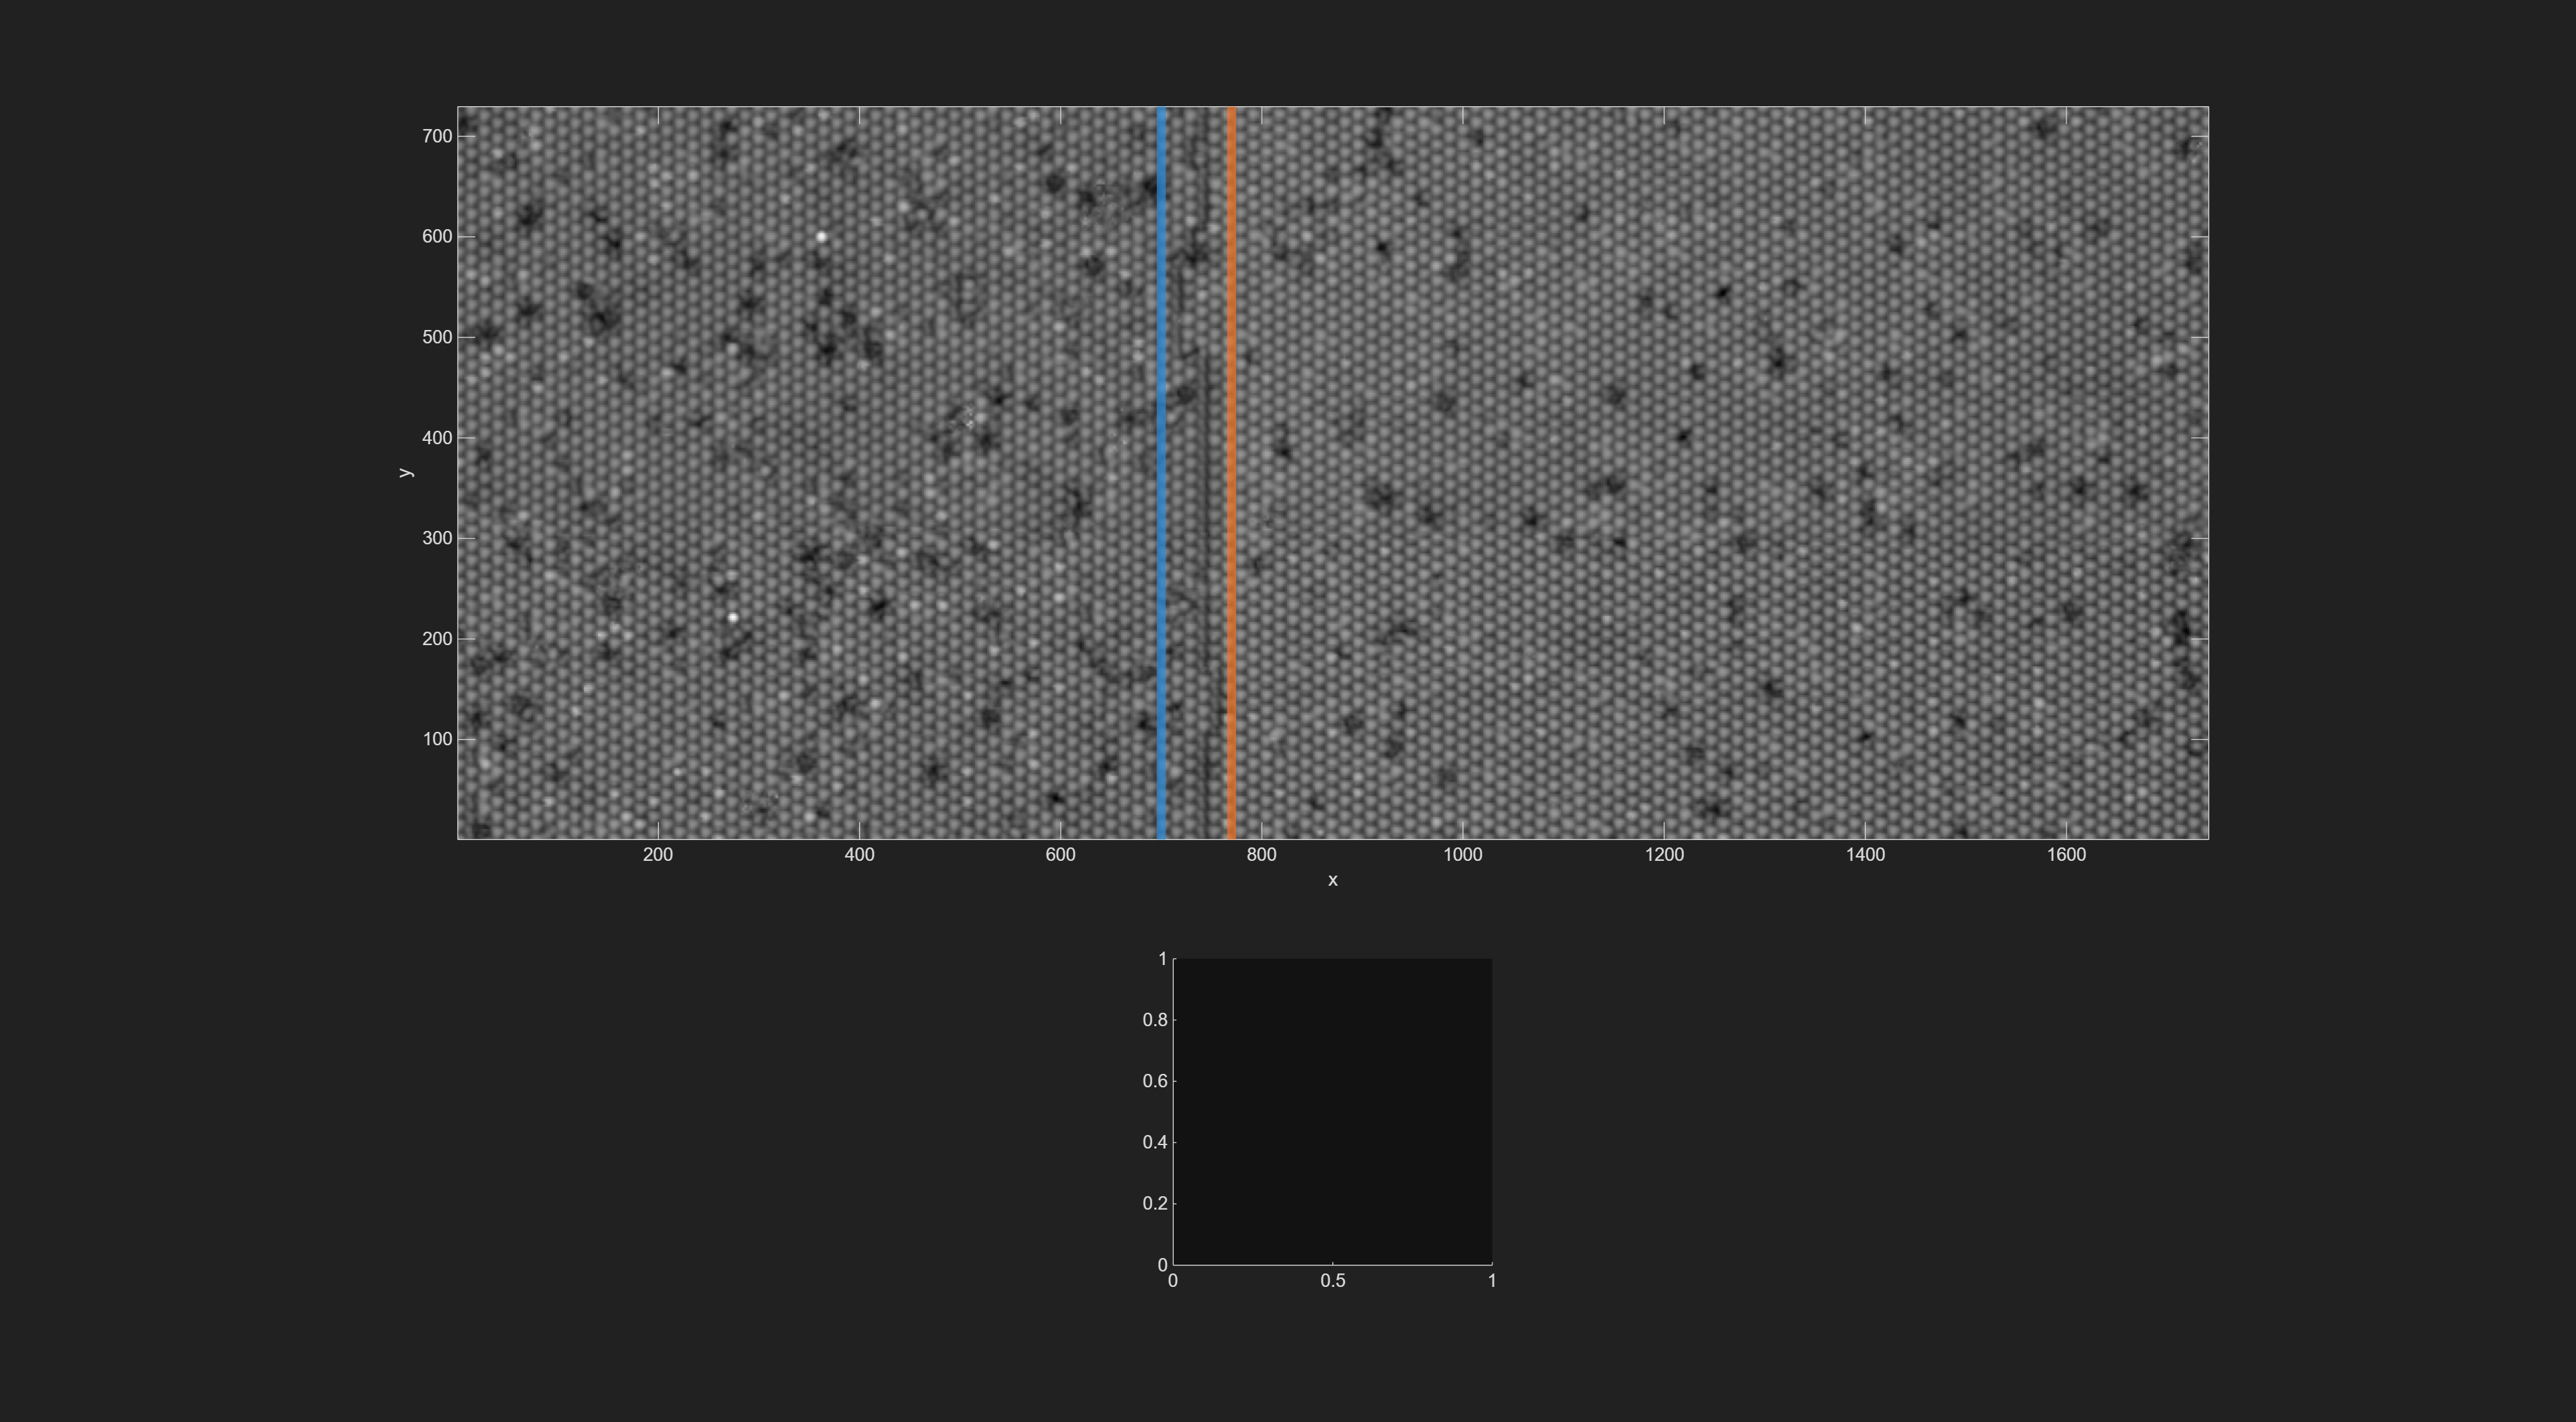

xline(margins(1),Color=co(1,:),LineWidth=5)
xline(margins(2),Color=co(2,:),LineWidth=5)

f1.CurrentAxes = axDos

f1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.1294 0.1294 0.1294]
    Position: [0.0027 1.2528 0.7484 0.7347]
       Units: 'normalized'

  Show all properties


% V 
rngs = [1 margins(1);margins(2) size(Gfinal0T,1)];
for iphase = 1:2
    gs(:,iphase) = squeeze(mean(mean(Gfinal0T(rngs(iphase,1):rngs(iphase,2),:,:))));
end


plot(vm,gs)
xline(vm(iv))
xlim([-1 1]*.6)
legend(["T_C" "T_A"])
xlabel('V (V)')
ylabel('Averaged LDOS (Arb)')

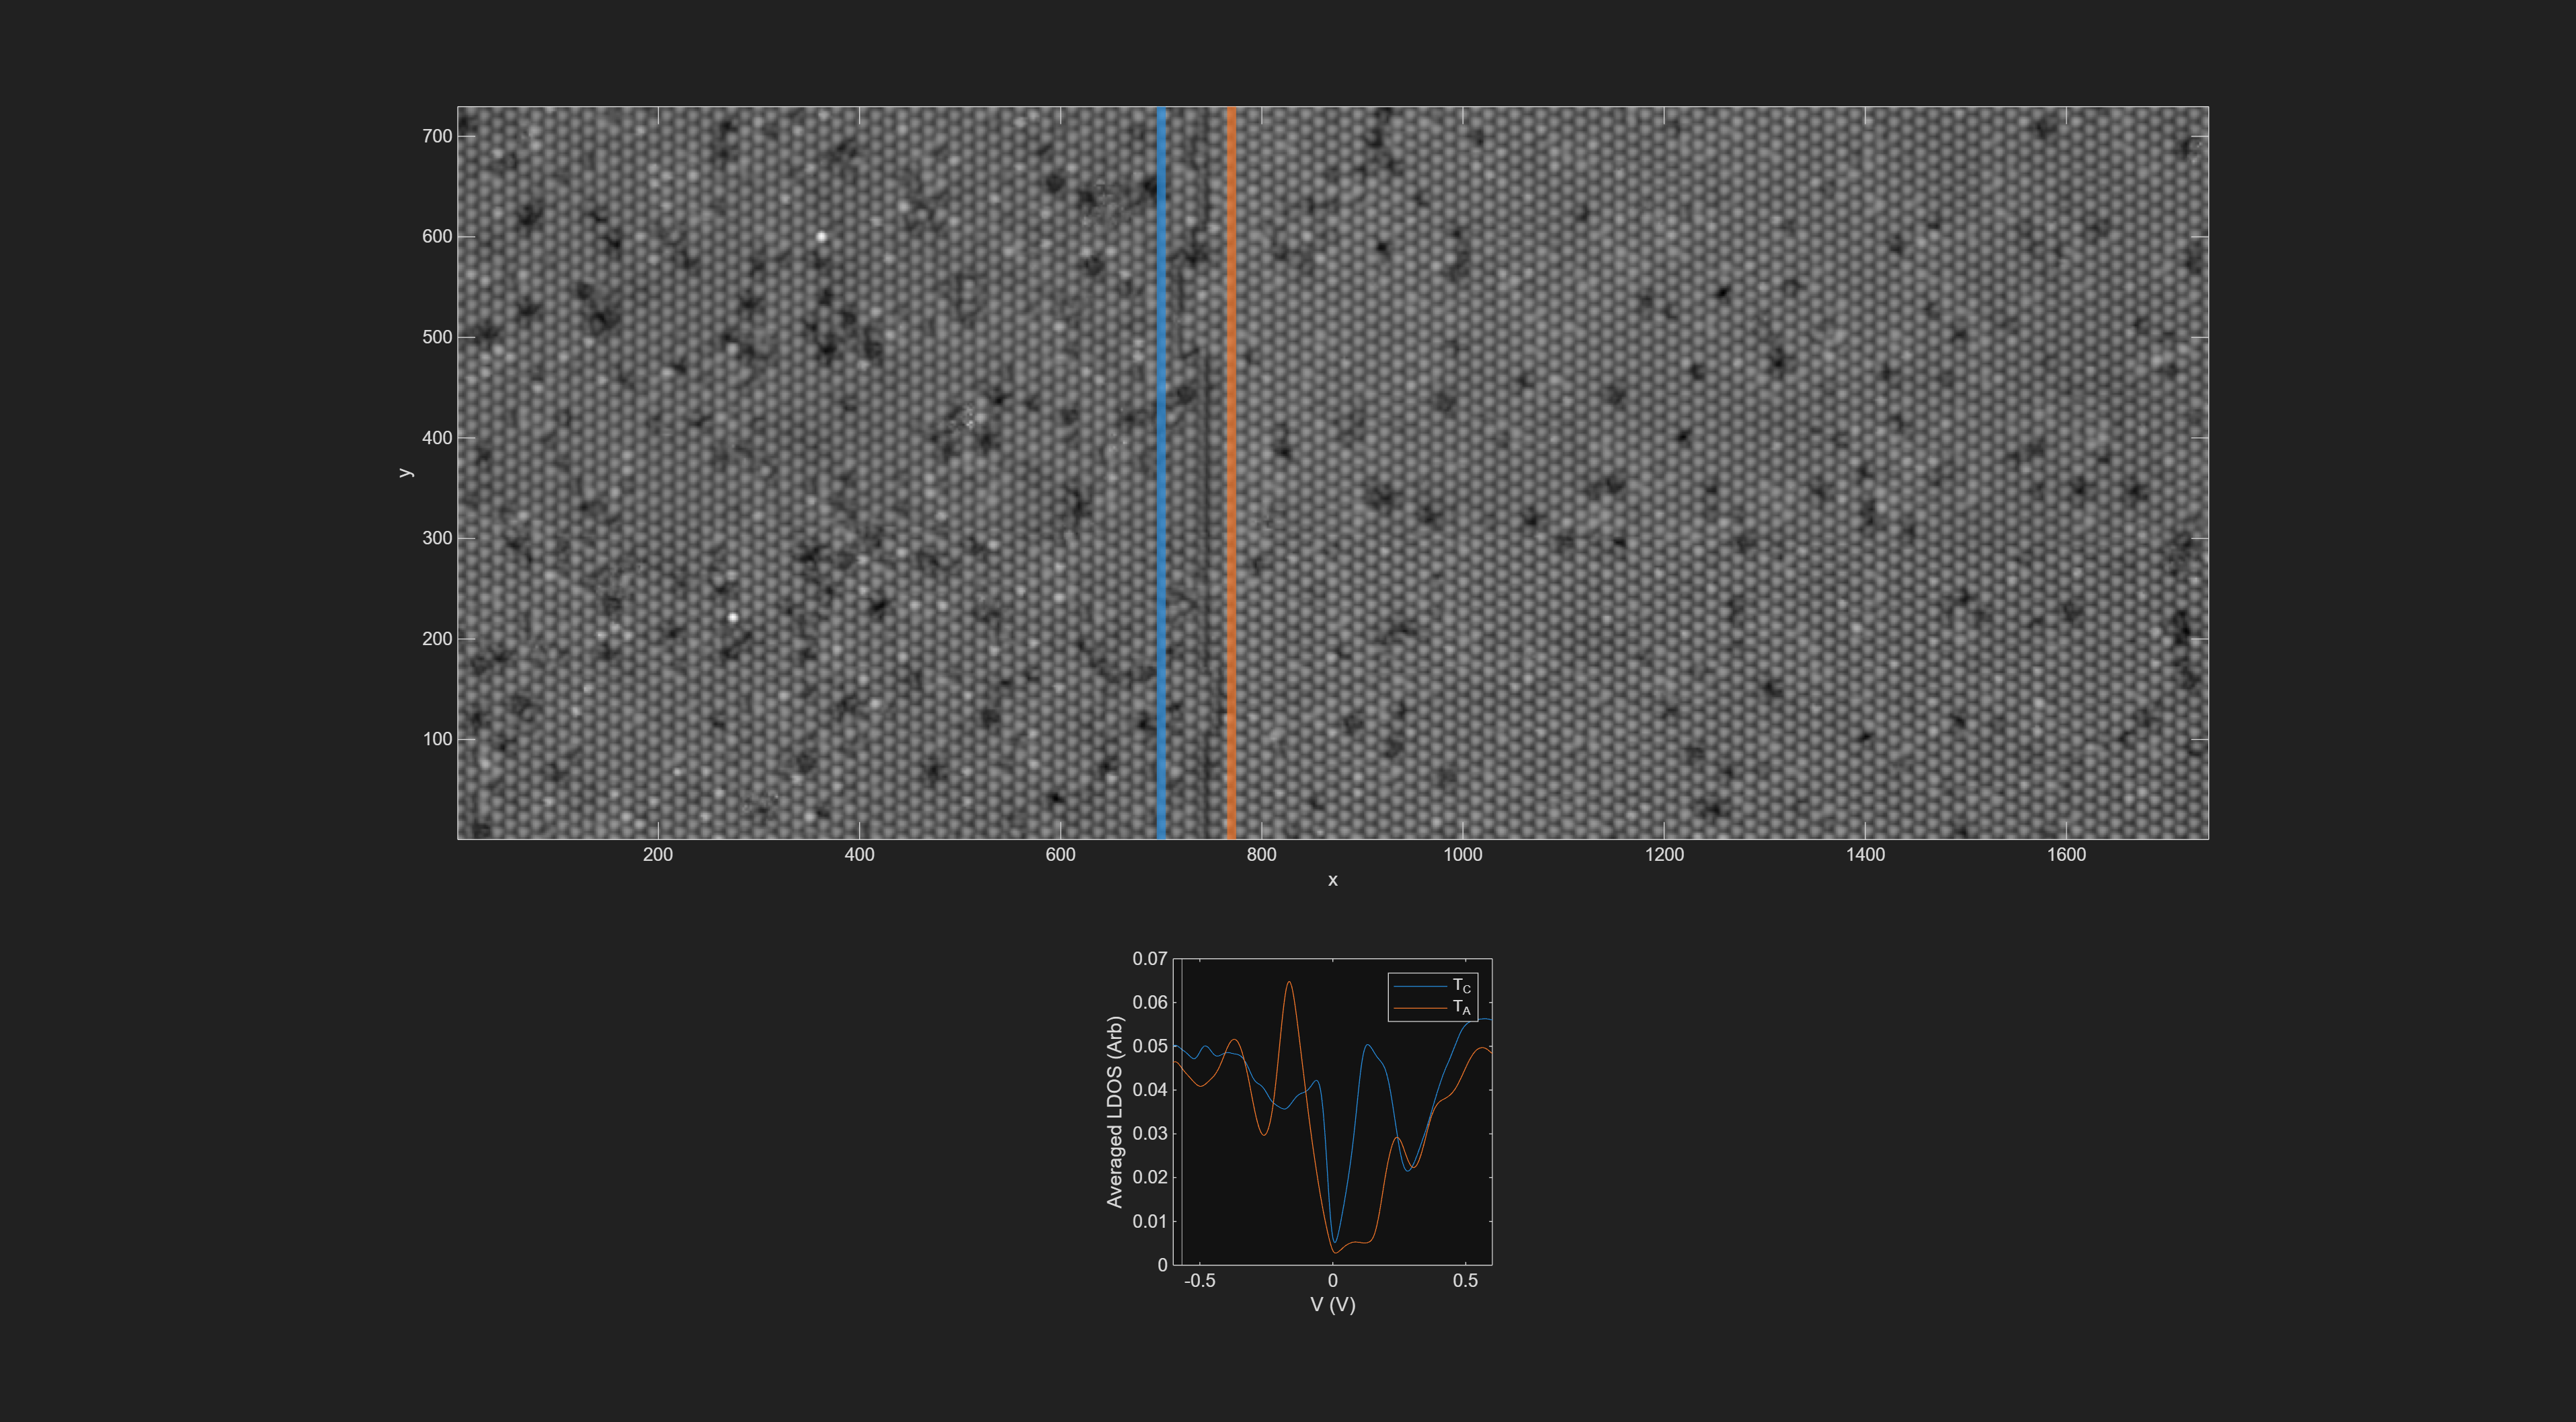

waterMark()